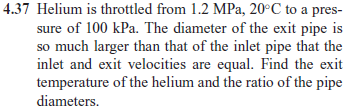

# constants

u = symunit;
He = ig('Helium');

# state 1

% ------------------------
% given
p1 = 1.2*u.MPa;
T1 = c2k(20*u.Celsius);
% ------------------------
% density
rho1 = simplify(p1/(He.R*T1));
% ------------------------

# state 2

% ------------------------
% given
p2 = 100*u.kPa;
T2 = T1; % throtting process
% ------------------------
% density
rho2 = simplify(p2/(He.R*T2));
% ------------------------

# conservation of mass

% mdot1 == mdot2
% rho1*A1*V1 == rho2*A2*V2
% rho1*(pi*D1^2/4)*V1 == rho2*(pi*D2^2/4)*V1
% rho1*D1^2 == rho2*D2^2
% D2/D1 == sqrt(rho1/rho2)
D2_D1 = sqrt(rho1/rho2);
D2_D1_vpa = vpa(D2_D1, 3) %#ok

$$D2\_D1\_vpa = 3.46$$

clear D2_D1_vpa;